# What should the basis functions be for fitting the raw tongue/lip signals?

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD, NADH, and keratin in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

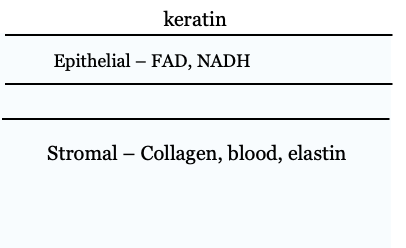

We have data about the excitations of each of these fluorophores.  These are in the isetfluorescence repository.  We are going to read them in and we are also going to read in some examples of raw data taken from our subjects' tongues and lips.  This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
waves = 500:600;

## Load fluorophore emissions

We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreEmissions.  Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  Here we plot typical examples of each of the different fluorophores emission spectra. They differ between labs, but the slopes here are typical.

% fluorophoreNames = {'CollagenWuQu','elastin_webfluor','KeratinWuQu',...
%     'NADH_webfluor','FADBecker','protoporphyrin'};

fluorophoreNames = {'KeratinValdez','FADValdez'};
fluorophores = fiLoadBasis(fluorophoreNames,'wave',waves);

## Read in the oxy data

Let's amend the fluorophore basis by adding in collagen after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

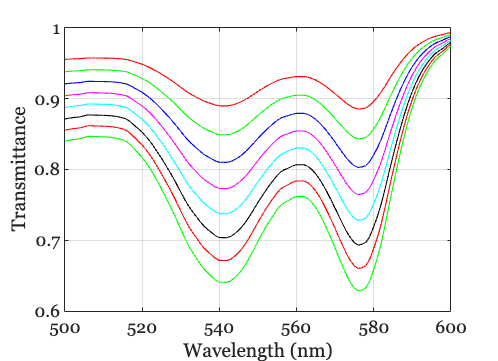

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',waves);

ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(waves,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

This should also become a function that takes a fluorophore and modifies it by blood transmittance with some arguments.  We experimented and it seemed we only needed elastin with a blood density of 2.5

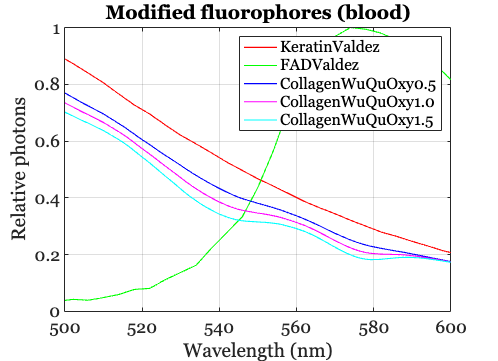

collagenF = fiReadFluorophore('CollagenWuQu');
collagen = fluorophoreGet(collagenF,'normalized emission','wave',waves);

for od = (.5:.5:1.5)
    oxyblood.opticalDensity = od;
    transmittance = oxyblood.transmittance;
    collagenO = collagen(:) .* transmittance(:);
    fluorophores = [fluorophores, collagenO(:)];
    fluorophoreNames{end+1} = sprintf('CollagenWuQuOxy%0.1f',od);
end

ieFigure;
plot(waves,fluorophores); title('Modified fluorophores (blood)')
xlabel('Wavelength (nm)'); ylabel('Relative photons'); grid on;
legend(fluorophoreNames);

## Read a couple of raw data sets

This is the database of raw measurements.

T = oeDatabaseCreate;

## Lip:  405 and 415

We illustrate with Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

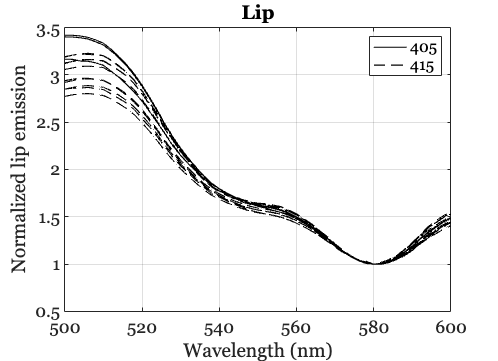

files405 = ieTableGet(T,'subject','Z',...
    'substrate','lip',...
    'e wave',405); % ,...
    % 'e level',980);
data405 = oeReadFiles(files405,'wave',waves,'normalized wave',580);

files415 = ieTableGet(T,'subject','Z',...
    'substrate','lip',...
    'e wave',415); % ,...
    % 'e level',910);
data415 = oeReadFiles(files415,'wave',waves,'normalized wave',580);

lipData = cat(2,data405, data415);

ieFigure;
for ii=1:size(data405,2)
    hA = plot(waves,data405(:,ii),'k-'); hold on;
end
for ii=1:size(data415,2)
    hB = plot(waves,data415(:,ii),'k--'); hold on;
end

legend([hA,hB],{'405','415'});
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;
title('Lip');

## Tongue: Pool 405 and 415

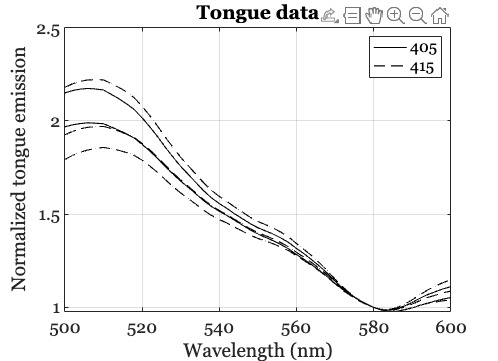

files405 = ieTableGet(T,'subject','Z',...
    'substrate','tongue',...
    'e wave',405,...
    'e level',980);
data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);

files415 = ieTableGet(T,'subject','Z',...
    'substrate','tongue',...
    'e wave',415,...
    'e level',910);
data415 = oeReadFiles(files415,'waves',waves,'normalized wave',580);

tongueData = cat(2,data405, data415);

% files450 = ieTableGet(T,'subject','Z','substrate','tongue','e wave',450,'e level',870,'return','files');

ieFigure;
for ii=1:size(data405,2)
    hA = plot(waves,data405(:,ii),'k-'); hold on;
end
for ii=1:size(data415,2)
    hB = plot(waves,data415(:,ii),'k--'); hold on;
end

legend([hA,hB],{'405','415'});
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission')
grid on; 
title('Tongue data');

## Select the fluorophores for a basis

Above, we plasted all the fluorophore emissions data in a matrix (fluorophores).  We check how well the full matrix can predict the data samples.  We think it won't without accounting for blood.  

The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


## **Non-negative lip**

The LS fits are close, but they have negative values for the different fluorophore contributions.  We don't think that is OK.  So we force the solutions to be nonnegative using this method.  

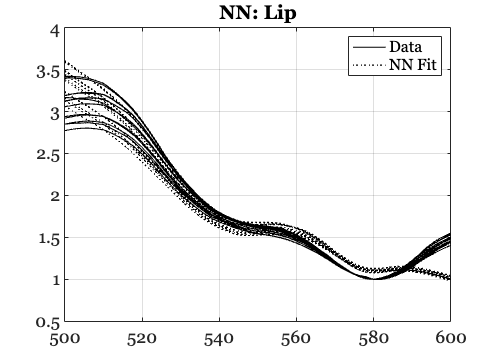

wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

for dd = 1:size(lipData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
end

ieNewGraphWin;
for ii=1:size(lipData,2)
    hA = plot(waves,lipData(:,ii),'k-'); hold on;
end

for ii=1:size(lipData,2)
hB = plot(waves,fluorophores*wgtsNN(:,ii),'k:'); hold on;
end

grid on; legend([hA,hB],{'Data','NN Fit'});
title('NN: Lip')

disp(fluorophoreNames'); disp(wgtsNN);

    {'KeratinValdez'     }
    {'FADValdez'         }
    {'CollagenWuQuOxy0.5'}
    {'CollagenWuQuOxy1.0'}
    {'CollagenWuQuOxy1.5'}

         0         0         0         0         0    0.1942    0.2949         0         0         0         0    0.0609    0.2952    0.4380
    0.1470    0.2054    0.1444    0.2376    0.2048    0.2628    0.2758    0.2324    0.2403    0.2114    0.2111    0.2593    0.2778    0.2870
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.1061    4.8264    5.1290    4.7881    4.9583    4.3517    4.1117    4.8890    4.8909    4.9453    4.9486    4.5116    4.0688    3.7922



## **Non-negative tongue**

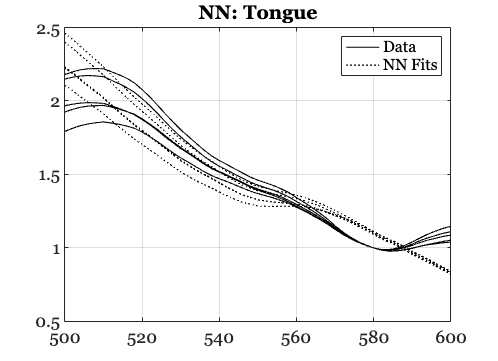

wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

for dd = 1:size(tongueData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
end

ieFigure;
for ii=1:size(tongueData,2)
    hA = plot(waves,tongueData(:,ii),'k-'); hold on;
end
for ii=1:size(tongueData,2)
    hB = plot(waves,fluorophores*wgtsNN(:,ii),'k:'); hold on;
end
grid on; 
legend([hA,hB],{'Data','NN Fits'});
title('NN: Tongue'); 


disp(fluorophoreNames'); disp(wgtsNN);

    {'KeratinValdez'     }
    {'FADValdez'         }
    {'CollagenWuQuOxy0.5'}
    {'CollagenWuQuOxy1.0'}
    {'CollagenWuQuOxy1.5'}

    2.4915    2.5043    2.3488    2.5719    2.4837
    0.3738    0.3353    0.4319    0.3286    0.3812
         0         0         0         0         0
         0         0         0         0         0
         0    0.2255         0    0.2291         0



These fits are a little worse, but not terrible.  The main thing to note is the modulation of the data around the predictions.  We think that miss is because we haven't accounted for the blood.

The fits are better, with the biggest miss around 600 nm. Let's look at the weights.  It appears only the 2nd blood modified collagen is used.  It is also using NADH, FAD, and porphyrin.

Delete

## Lips

Fit for lips here. Ordinary least squares.

% wgtsLS = pinv(fluorophores)*lipData;
% 
% ieFigure;
% for ii=1:size(lipData,2)
%     hA = plot(waves,lipData(:,ii),'k-'); hold on;
% end
% for ii=1:size(lipData,2)
%     hB = plot(waves,fluorophores*wgtsLS(:,ii),'k--'); hold on;
% end
% grid on;
% legend([hA,hB],{'Lip data','LS est'});

## Tongue

Least squares

% wgtsLS = pinv(fluorophores)*tongueData;
% 
% ieFigure;
% for ii=1:size(tongueData,2)
%     hA = plot(waves,tongueData(:,ii),'k-'); hold on;
% end
% for ii=1:size(tongueData,2)
%     hB = plot(waves,fluorophores*wgtsLS(:,ii),'k:'); hold on;
% end
% 
% legend([hA,hB],{'Tongue data','LS est'});
% disp(fluorophoreNames'); disp(wgtsLS);